# Influence of Cholesterol on Heart Disease (Binomial Sampling)

*Dr. Eric S. Wright*

*The University of Montana Western*

# 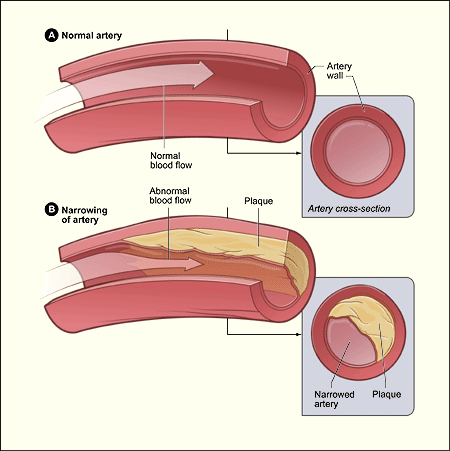

Atheroschlerosis - public domain image: https://simple.wikipedia.org/wiki/Arteriosclerosis#/media/File:Atherosclerosis_diagram.png

## Introduction

Heart disease is often linked to many different factors that are tied to lifestyle, genetics, physiology, etc. In this LiveScript, we develop a methodology for determining whether there is a significant relationship between a single factor (specifically: overall cholesterol) and the presence of heart disease. We base our work on the well-known, publicly available Cleveland data on heart disease in medical study subjects. 

This program has the following objectives:

- Load the external Cleveland data into a MATLAB table.

- Split the data into two sets: one for which test subjects have a cholesterol level in the normal range and one for which test subjects have high cholesterol. In this study, the high cholesterol group will serve as the control population and the normal cholesterol group will serve as the experimental population.

- Use the geometric framwork to repeatedly sample subjects (with replacement) from the control population. Count the number of healthy subjects we observed before encountering the first subject with heart disease. These counts constitute the control data set. Use a similar technique to build an experimental data set from the experimental population.

- Compute descriptive statistics of the control data. This will include several measures of central tendency, variability, asymmetry, and the importance of outliers.

- Produce several visualizations of the data including histograms and box and whisker plots.

- Fit a probability distribution (the geometric distribution in this case) to the data using parameter estimation and validate the fit of the model by comparing the relative frequency histogram of the data set to a bar graph of the theoretical distribution, comparing the empirical shape parameters of the data to the theoretical shape parameters of the distribution, examining a quantile-quantile plot, and performing Pearson's goodness of fit test.

- Test the null hypothesis that there is no significant difference between the experimental data and the values our theoretical model for the control data leads us to expect.

- Test the null hypothesis that there is no significant difference between the mean of the experimental data and the expected mean of our theoretical distribution (or that there is no significant difference between the means of the control and experimental data sets).

- Test the null hypothesis that there is no significant difference between the variance of the experimental data and the expected variance of our theoretical distribution (or that there is no significant difference between the variances of the control and experimental data sets).

- Use bootstrap sampling methods and perform tests for differences between means based upon the bootstrap samples. 

## Data Collection and Wrangling

Clear all memory, close all figures, and clean out the command line history

clear all; close all; clc;

Since we will be sampling randomly from data sets, choose the seed for the random number generator for reproducibility. Disable this if you want to replicate this experiment multiple times.

rng(2);

Import the UCI Machine Learning Repository Cleveland data into a table. I used the processed.cleveland.data data set and saved it under the name "processed.cleveland.csv". The readtable command loads the data from the file into an internal MATLAB table. However, I need to manually set the names of the columns for this table. I obtain these names from the documentation UCI provided for the data set. The page for obtaining this data can be found here: [https://archive.ics.uci.edu/ml/datasets/heart+disease](https://archive.ics.uci.edu/ml/datasets/heart+disease)

VarNames={'age','sex','cp','trestbps','chol','fbs','restecg','thalach','exang','oldpeak','slope','ca','thal','num'};
cleveland_data=readtable('Data/processed.cleveland.csv');
cleveland_data.Properties.VariableNames=VarNames

cleveland_data = 303×14 table
    age    sex    cp    trestbps    chol    fbs    restecg    thalach    exang    oldpeak    slope    ca    thal    num
    ___    ___    __    ________    ____    ___    _______    _______    _____    _______    _____    __    ____    ___

    63      1     1       145       233      1        2         150        0        2.3        3      0      6       0 
    67      1     4       160       286      0        2         108        1        1.5        2      3      3       2 
    67      1

The data set contains more attributes than we really care about.  All we need to know is whether a subject has high cholesterol (>200mg/dl) and whether or not they have heart disease (measurable narrowing of the arteries (num>=1). We'll create a simplified data set that summarizes the membership of each subject in these two categories.

cleveland_data.high_chol=cleveland_data.chol>200

cleveland_data = 303×15 table
    age    sex    cp    trestbps    chol    fbs    restecg    thalach    exang    oldpeak    slope    ca    thal    num    high_chol
    ___    ___    __    ________    ____    ___    _______    _______    _____    _______    _____    __    ____    ___    _________

    63      1     1       145       233      1        2         150        0        2.3        3      0      6       0       true   
    67      1     4       160       286      0        2     

cleveland_data.heart_disease=cleveland_data.num>0

cleveland_data = 303×16 table
    age    sex    cp    trestbps    chol    fbs    restecg    thalach    exang    oldpeak    slope    ca    thal    num    high_chol    heart_disease
    ___    ___    __    ________    ____    ___    _______    _______    _____    _______    _____    __    ____    ___    _________    _____________

    63      1     1       145       233      1        2         150        0        2.3        3      0      6       0       

Our goal is to produce two separate data sets. The first will be created by randomly sampling 50 groups of 30 subjects each (with replacement) from the population that has highl cholesterol levels (above 200 mg/dl). These are the people with a 0 in the high_chol column. From each sample, we will count the number with heart disease. Each count represents a single data point in our first data set. Then, we'll randomly sample 50 groups of 30 subjects each (again with replacement) from the population that has high cholesterol levels. We'll produce similar counts for them.

N_control=50

N_control = 50

N_experimental=50

N_experimental = 50

normal_chol_idx=~(cleveland_data.high_chol);
high_chol_idx=cleveland_data.high_chol;
ExperimentalData=zeros(1,N_experimental);
ControlData=zeros(1,N_control);
for i=1:N_control
    x=0;
    hd=randsample(cleveland_data.heart_disease(high_chol_idx),1,true);
    while(~hd)
        hd=randsample(cleveland_data.heart_disease(high_chol_idx),1,true);
        x=x+1;
    end
    ControlData(i)=x;
end
ControlData

ControlData =      1     8     0     1     0     4     4     1     0     0     0     2     0     1     0     0     2     3     2     1     1     0     0     0     0     2     1     2     1     0     0     0     4     0     3     0     1     1     1     0     2     0     2     0     0     0     3     0     2     1



for i=1:N_experimental
    x=0;
    hd=randsample(cleveland_data.heart_disease(normal_chol_idx),1,true);
    while(~hd)
        hd=randsample(cleveland_data.heart_disease(normal_chol_idx),1,true);
        x=x+1;
    end
    ExperimentalData(i)=x;
end
ExperimentalData

ExperimentalData =      3     3     6     0     2     2     1     0     0     0     0     1     5     0     0     5     4     1     2     1     0     0     0     0     0     1     1     2     4     2     0     1     0     3     2     0     0     0     5     3     1     0     0     3     0     5     6     7     1     0


At this point, we have two data sets. The first, ControlData, represents the number of people among samples of 30 drawn from the high cholesterol population who also have signs of heart disease. The second, ExperimentalData, represents the number of people among samples of 30 drawn from the normal cholesterol population who also have signs of heart disease. Next, we'll proceed to compute a variety of descriptive statistics from and construct visualizations for the first data set so that we may compare the values from the second data set to them.

## Descriptive Statistics

Summarize the basic, descriptive statistics for the control data set.

ds=descriptiveStats(ControlData)

ds = struct with fields:
         Mean: 1.1400
       Median: 1
         Mode: 0
          Max: 8
          Min: 0
        Range: 8
       StdDev: 1.5364
     Variance: 2.3604
    Quartiles: [0 1 2]
          IQR: 2
     Skewness: 2.1139
       Bowley: 0
     Kurtosis: 8.9544


## Visualizations

A histogram summarizes the frequencies of each value found in the control data set.

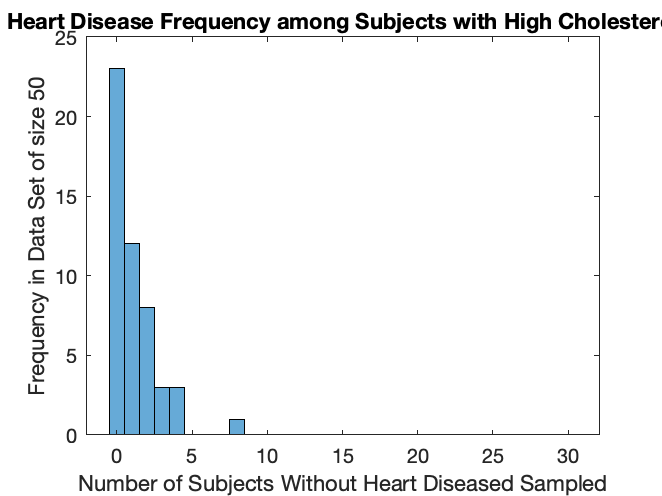

figure(1)
histogram(ControlData,-0.5:1:30.5)
title("Heart Disease Frequency among Subjects with High Cholesterol")
xlabel("Number of Subjects Without Heart Diseased Sampled")
ylabel("Frequency in Data Set of size 50")

A box and whisker plot summarizes the quartiles and outliers of the control data set.

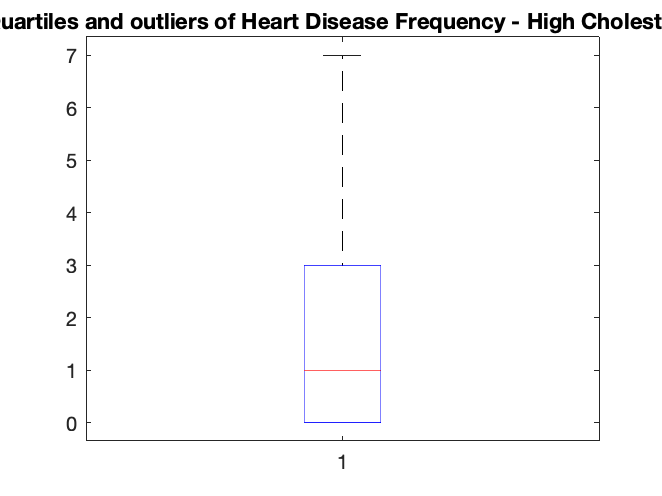

figure(2)
boxplot(ExperimentalData)
title("Quartiles and outliers of Heart Disease Frequency - High Cholesterol")

## Parameter Estimation

### Maximum Likelihood Estimation

MATLAB has a built in maximum likelihood estimation function (mle). We can use it to perform parameter estimation for many of the common probability distributions. 

n=30;
p=mle(ControlData,"distribution","Geometric")

p = 0.4673

### Validation

Create a geometric distribution object that we calibrate with our values of $n$ and $p$.

pd=makedist("NegativeBinomial","R",1,"p",p);

Build the arrays of observed frequencies from the control data set and expected frequencies from the theoretical distribution. Compare these frequencies with a side-by-side bar graph.

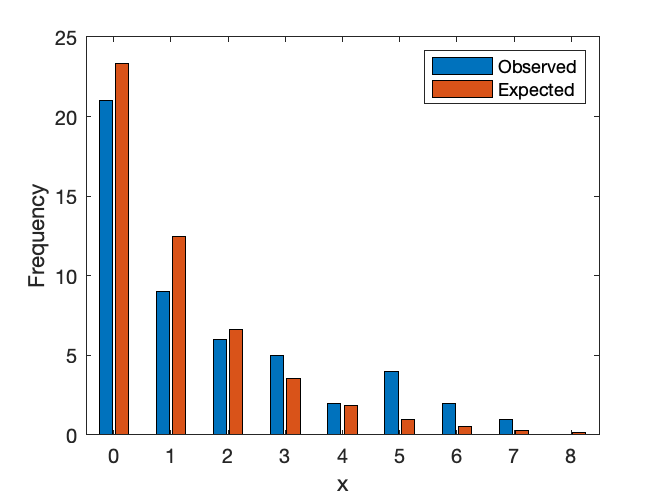

figure(3)
[ObservedFrequencies,ExpectedFrequencies]=frequencyPlot(ExperimentalData,pd);

Compute and compare the empirical and theoretical shape parameters.

shapes=compareShapeParameters(ControlData,pd)

shapes = 2×4 table
                   MEAN    VARIANCE    SKEWNESS    KURTOSIS
                   ____    ________    ________    ________

    Empirical      1.14     2.3604      2.1139      8.9544 
    Theoretical    1.14     2.4396         2.1      9.4099 


Construct a quantile-quantile plot that compares the quantiles of the control data set to the corresponding quantiles of the theoretical distribution

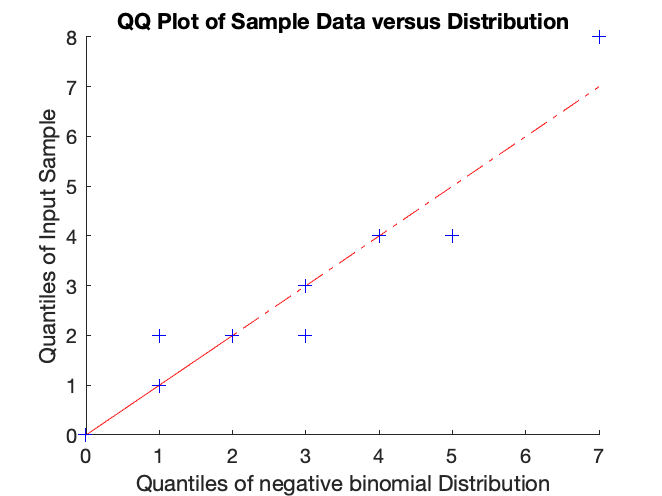

figure(4)
qqplot(ControlData,pd)

Finally, perform Pearson's goodness of fit test.

[h,pChi2,stats]=chi2gof(ControlData,'CDF',@pd.cdf,"NParams",1)

h = 0

pChi2 = 0.8412

stats = struct with fields:
    chi2stat: 0.3459
          df: 2
       edges: [4.9407e-324 0.8000 1.6000 2.4000 8.0000]
           O: [23 12 8 7]
           E: [23.3645 12.4465 6.6304 7.5586]


## Hypothesis Testing

### Fisher's Significance Testing

#### Geometric Test 

Since we were able to establish such strong validation for the fit between the geometric model and our control data, we are justified in conducting the geometric tests for differences between experimental data and behavior predicted by the model. The null hypothesis for this test is

$H_0$: *We will not observe significantly greater numbers of healthy test subjects before detecting our first case of heart disease in the normal cholesterol group compared to what the geometric model for the high cholesterol group leads us to expect.*

The p values resulting from the geometric test are computed as follows. Note that we are only testing for a decrease because of the single tailed nature of the geometric distribution.:

[pIncreaseDiscrete,~]=discreteSignificance(ExperimentalData,pd)

pIncreaseDiscrete =     0.1512    0.1512    0.0229    1.0000    0.2838    0.2838    0.5327    1.0000    1.0000    1.0000    1.0000    0.5327    0.0429    1.0000    1.0000    0.0429    0.0805    0.5327    0.2838    0.5327    1.0000    1.0000    1.0000    1.0000    1.0000    0.5327    0.5327    0.2838    0.0805    0.2838    1.0000    0.5327    1.0000    0.1512    0.2838    1.0000    1.0000    1.0000    0.0429    0.1512    0.5327    1.0000    1.0000    0.1512    1.0000    0.0429    0.0229    0.0122    0.5327    1.0000


sum(pIncreaseDiscrete<0.05)

ans = 7

Only a small minority of these p values fall below 5%, so we can safely conclude that we have insufficient justification for rejecting our null hypothesis.

#### One Sample T-Test

The good fit between the geometric model and the control data also provides justification for conduct a one sample t test for differences between the mean of the experimental set and the theoretical means predicted by the geometric distribution. The null hypothesis for this test is

$H_0$: There is no significant difference between the mean of the experimental data set and the theoretical mean predicted by the geometric distribution. This test can be performed as follows:

[h,pt,ci,stats]=ttest(ExperimentalData,pd.mean)

h = 0

pt = 0.0701

ci =     1.0957    2.2243


stats = struct with fields:
    tstat: 1.8517
       df: 49
       sd: 1.9858


The p value (pt) for this test is substantially larger than 5%. This fails to provide evidence for rejecting the null hypothesis that the theoretical mean and mean of the experimental sample are the same. The ttest function also provides us with a 95% confidence interval that establishes the location of the true mean for the population that the experimental data is taken from.

#### Two Sample T Test

Alternatively, we could address the slightly different task of determining if there is a difference between the means of the control and experimental data sets by conducting the two sample t test. Before doing so, it is worth investigating the similarity between the control and experimental variances, because this can impact how we design our two sample T test. There are two approaches we can follow:

First, since we know the geometric distribution fits our control data well, we are justified in conducting the $\chi^2$ test for differences between the sample variance of our experimental data set and our theoretical variance predicted by the geometric distribution. The null hypothesis for the $\chi^2$ test is

$H_0$*: There is no significant difference between the variance of the experimental data and the theoretical variance predicted by the geometric distribution.*

and we may perform the test as follows:

[h,pvar,ci,stats]=vartest(ExperimentalData,pd.var)

h = 1

pvar = 0.0081

ci =     2.7515    6.1233


stats = struct with fields:
    chisqstat: 79.2015
           df: 49


We can se that the p vlaue is too high to reject the null hypothesis that there is no difference between the variances. The $\chi^2$ test also supplies a 95% confidence interval for the true variance of the population the experimental data was sampled from.

If we had been unable to establish such a good fit between our geometric model and our control data, we could alternatively investigate similarities between the variances of the populations the experimental and control data sets were sampled from by conducting the F test. While this is unnecessary in our particular case, we'll still perform it. The null hypothesis for this test is

$H_0$*: There is no significant difference between the variance of the experimental data set and the variance of the control data set. *

We perform the test as follows:

[h,pvar2,ci,stats]=vartest2(ExperimentalData,ControlData)

h = 0

pvar2 = 0.0876

ci =     0.9291    2.8850


stats = struct with fields:
    fstat: 1.6372
      df1: 49
      df2: 49


Again, the p value is too high to justify rejecting the null hypothesis that there is no difference between the variance. The F test also supplies a 95% confidence interval for the true ratio between the variances of the experimental and control populations.

Both tests allow us to assume that the experimental and control variances are at least somewhat similar. However, the confidence intervals we've computed are also somewhat large, so there is some uncertainty surrounding this assumption. While we are probably still justified in performing the two sample t test with an equal variance assumption in place, it would be more conservative of us to drop that assumption. 

The null hypothesis for the two sample t test (without an assumption of equal variances between the experimental and control samples) is 

$H_0$*: There is no significant difference between the means of the experimental and control data sets.* 

This test bypasses the need of knowing that the geometric distribution is the model for our original counts of heart disease-free test subjects and having access to the theoretical mean of that distribution. We simply treat our control and experimental data sets as two independent samples (with potentially different sample variances) and test for equality of the two sample means. This would have been an appropriate choice of a hypothesis test for determining differences between our experimental and control measurements had we been unable to achieve a strong fit between our geometric model and the control data. While it is somewhat unnecessary in our case, we may perform this test as follows:

[h,pt2,ci,stats]=ttest2(ExperimentalData,ControlData,'Vartype',"unequal")

h = 0

pt2 = 0.1480

ci =    -0.1878    1.2278


stats = struct with fields:
    tstat: 1.4589
       df: 92.5946
       sd: [1.9858 1.5520]


Again, we have too large of a p value (pt2) to justify rejecting the null hypothesis that the means of the experimental and control samples are the same. The ttest2 function also provides us with a 95% confidence interval that establishes the location of the difference between the true means for the populations that the experimental and control data is taken from.

### Bootstrap Methods 

Bootstrap sampling provides us with a way of generating larger, synthetic data sets from our established control and experimental data sets through the practice of resampling. These methods can be used as alternative approaches for determining if there is a significant difference between the experimental and control means. They also completely sidestep the need for assuming that any particular model fits our experimental or control data sets well. Finally, they provide us with confidence intervals that may give us some insight into how our experiment might play out, were we to repeat it multiple times.

#### Bootstrap Confidence Interval

Simulate 2000 samples of 40 data points from the control data set and compute their means. This set of means is a bootstrap data set. Compute a 95%, two-tailed confidence interval from the bootstrap data set by locating its 2.5 and 97.5 percentiles. Determine where the mean of the experimental data set falls relative to the confidence interval.

B=2000;
[hbs,aslbs,cbs,statsbs]=bootstrpmean(ControlData,ExperimentalData,B)

hbs = 1

aslbs = 0.0105

cbs =     0.7600    1.6000


statsbs = struct with fields:
         MeanControl: 1.1400
    MeanExperimental: 1.6600
                 bsm: [2000×1 double]


Visualize the confidence interval and experimental mean on top of the bootstrap data set.

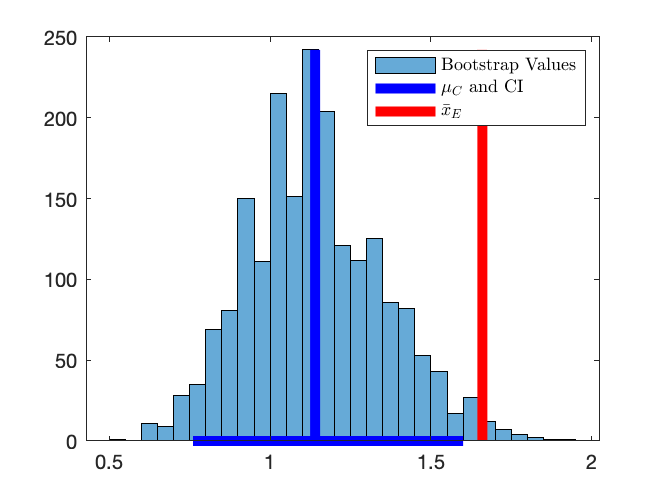

figure(5)
bootstrpmeanvis(cbs,statsbs)

We can see that the mean of our experimental data set falls well inside the bootstrap confidence interval. This is an indication that the mean of our experimental data set is similar to what we expect to see in typical control data.

#### Bootstrap Two Sample Test

We can also create a bootstrap sample from our experimental data set. This has the potential to give us a better picture of what might happen should we repeat our experiment multiple times. 

Create 2000 bootstrap samples from both the control and experimental data sets. The size of each sample taken from the control data set should mirror the size of the control data set. The size of each sample taken from the experimental data set should mirror the size of the experimental data set. For each sample, track the sample means and sample standard deviations as well as the two sample t statistic (that makes no assumption about similarity between control and sample variances). Since we have a bootstrapped data set of two-sample t statistics, we can perform the analog of a two sample t test by computing the Achieved Significance Level (ASL) for testing whether the t statistic ($t_0$) for the experimental and control samples is significantly different from what we expect of t statistics computed from bootstrap samples that have been shifted to share a common mean. The ASL represents the percentage of bootstrapped t statistics for which $t\ge t_0$. We can use it lieu of the p-value from the two sample t-test.

B=2000;
[hbs2,aslbs2,cbs2,statsbs2]=bootstrpmean2(ControlData,ExperimentalData,B)

hbs2 = 0

aslbs2 = 0.0610

cbs2 =     0.7600    1.6000
    1.1400    2.2200


statsbs2 = struct with fields:
         MeanControl: [2000×1 double]
    MeanExperimental: [2000×1 double]
                  xb: 1.1400
                  yb: 1.6600
                  zb: 1.4000


The value of the ASL is barly large enough to quantitatively suggest that there is no significant difference between the two sample means. For a visual investigation of the same effect, we compare the histograms of the two bootstrap data sets.

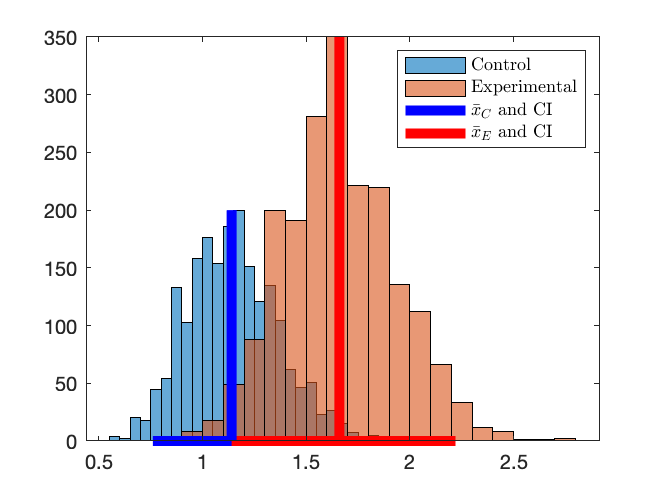

figure(6)
bootstrpmean2vis(cbs2,statsbs2)

Again, there appears to be just enough overlap between the bootstrap distributions as well as the two confidence intervals to suggest that the means are drawn from the same population. Note that this contradicts our previous results, but only weakly. 